**The attenuation coefficient for a phased array transducer used for heart tissue imaging can vary depending on several factors, including the frequency of the transducer, the angle of incidence, and the properties of the tissue being imaged.**

**In general, the attenuation coefficient for soft tissue such as the heart muscle is approximately 0.5 dB/cm/MHz. Therefore, for a typical frequency range of 1-5 MHz, the attenuation coefficient for a phased array transducer used for heart tissue imaging would be approximately 0.5-2.5 dB/cm.**

## frequency

clear; close all; clc;
% parameters we want to change (comment out what you want to change and
% change it in the for loops
tlt = 60 % tilt we want

tlt = 60

dw = 7 % amount of diverging waves we want

dw = 7

dwn = 4 % diverging wave number

dwn = 4

D2R = 60 %the degree wide we want

D2R = 60

fov = 120 % degree of field of view

fov = 120

ele = 64 % elements within the phased transducer we are using

ele = 64

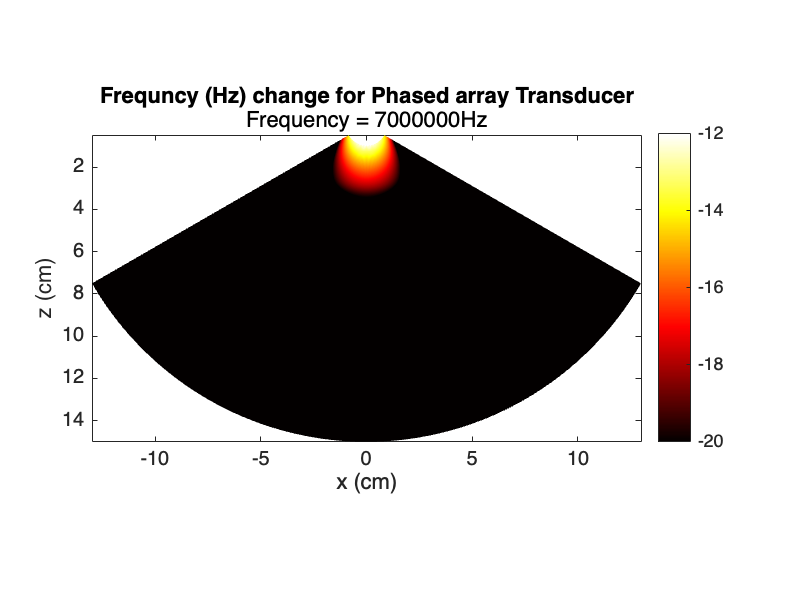

param = getparam('P4-2v');
freq_phase = [2e6, 3.5e6, 5.5e6,  7e6];
%% code from website with parameters put in 
for i = 1:length(freq_phase)

    param = setfield(param,'fc',freq_phase(i));
   
    param.TXapodization = cos(linspace(-1,1,ele)*pi/2);
    tilt = deg2rad(linspace(-1*tlt,tlt,dw)); % tilt angles in rad
    txdel = cell(7,1); % this cell will contain the transmit delays
    
        for k = 1:dw
            txdel{k} = txdelay(param,tilt(k),deg2rad(D2R));
        end
            % stem(txdel{1}*1e6)
            % xlabel('Element number')
            % ylabel('Delays (\mus)')
            % title('TX delays for a 60{\circ}-wide -20{\circ}-tilted wave')
            % axis tight square
    
    
    [xi,zi] = impolgrid([100 100],15e-2,deg2rad(fov),param);
    option.WaitBar = false;
    param.attenuation = 1.5;  
    P = pfield(xi,0*xi,zi,txdel{dwn},param,option);
        pcolor(xi*1e2,zi*1e2,20*log10(P/max(P(:))))
        shading interp
        xlabel('x (cm)')
        ylabel('z (cm)')
        title('Frequncy (Hz) change for Phased array Transducer')
        subtitle(['Frequency = ' num2str(freq_phase(i)) 'Hz'])
        axis equal ij tight
        caxis([-20 0]) % dynamic range = [-20,0] dB
        cb = colorbar;
        cb.YTickLabel{end} = '0 dB';
        colormap(hot)
   saveas(gcf,[num2str(freq_phase(i)) 'Frequncy (Hz).jpg'])
end